# Helium

#### Basis Functions

Z = 2;
a = [14.899983,2.726485,0.757447,0.251390];
n = length(a);
sympref('FloatingPointOutput',true);
syms chi(x) chi2(al,x)
chi(x) = exp(-a*x^2);
chi2(al,x) = exp(-al*x^2);
Chi = formula(chi);

#### Overlap Matrix


$$S_{pq} = \langle \chi_p|\chi_q\rangle$$


S = zeros(n,n);
for p=1:n
    for q=1:n
        S(p,q) = int(4*pi*x^2*Chi(p)*Chi(q),x,0,inf);
    end
end
S;
%Diagonalization
X = zeros(n,n);
[U,s] = eig(S)

U =     0.9445   -0.3215    0.0673    0.0071
   -0.3148   -0.8267    0.4601    0.0757
    0.0927    0.4507    0.8154    0.3512
   -0.0165   -0.1001   -0.3447    0.9332


s =     0.0163         0         0         0
         0    0.1309         0         0
         0         0    1.1541         0
         0         0         0   17.7758


for i=1:n
    X(i,:) = U(i,:)./sqrt(diag(s)');
end
X;

#### Hamiltonian

$H_{pq} = \langle\chi_p|T| \chi_q\rangle + \langle\chi_p|V| \chi_q\rangle$T

T = zeros(n,n);
for p=1:n
    for q=1:n
        T(p,q) = 8*pi*(a(q)*a(p))*int(x^4*Chi(p)*Chi(q),x,0,inf);
    end
end
T;
V = zeros(n,n);
for p=1:n
    for q=1:n
        V(p,q) = 4*Z*pi*int(x*Chi(p)*Chi(q),x,0,inf);
    end
end
V;
H0 = T-V;

#### Direct and Exchange Integrals

%Store all the integrals: cell element pq contains the
%matrix whose elements rs are the integrals at pqrs fixed
l = zeros(n,n);
D_pq = cell(n,n); %Direct term
for p=1:n
    for q=1:n
        for r=1:n
            for s=1:n
                f = @(r1,r2) 16*pi^2*r1.^2.*r2.^2.*exp(-a(p)*r1.^2)...
                    .*exp(-a(r)*r2.^2).*abs(r1-r2).*exp(-a(q)*r1.^2)...
                    .*exp(-a(s)*r2.^2);
                l(r,s) = integral2(f,0,inf,0,inf);
            end
        end
        D_pq{p,q} = l;
    end
end

l = zeros(n,n);
E_pq = cell(n,n); %Exchange term (p, s excanged)
for p=1:n
    for q=1:n
        for r=1:n
            for s=1:n
                f = @(r1,r2) 16*pi^2*r1.^2.*r2.^2.*exp(-a(p)*r1.^2)...
                    .*exp(-a(r)*r2.^2).*abs(r1-r2).*exp(-a(s)*r1.^2)...
                    .*exp(-a(q)*r2.^2);
                l(r,s) = integral2(f,0,inf,0,inf);
            end
        end
        E_pq{p,q} = l;
    end
end

#### Self-Consistent Procedure

F = zeros(n,n); %initialization of Fock matrix
Fx = zeros(n,n); %initialization of transormed Fock matrix (X'FX)
D = zeros(n,n); %initial guess for density matrix
check = 1;
old_eval = 0;
eval = zeros(n);
convergence = 1e-10;
i = 0;

while check>convergence
    i=i+1;                                  % count cicle
    old_eval = eval(1);
    F=FockMatrix(n,Z,D,D_pq,E_pq,H0);       % build Fock matrix
    Fx=X'*F*X;                              % Transoform F matrix
    [Cx,eval_unoredered]=eig(Fx);           % diagonalize Fx
    [eval,perm]=sort(diag(eval_unoredered));% order eigenvalues
    tmp=Cx;
    for k=1:n
        Cx(:,k)=tmp(:,perm(k));             % correspon. evec
    end
    C = X*Cx;                               % basis exp. coef.
    %Normalize eigenvectors C
    for k=1:n
        C(:,k)=C(:,k)/norm(C(:,k));
    end
    D = C(:,1)*C(:,1)';
    check = abs(eval(1)-old_eval);
    eval(1);
end
E = 0.5*sum(D(:).*(H0(:)+F(:)))*27.2114;

#### Final result for Helium

syms Psi(x)
Psi(x)=-(C(1,1)*chi2(a(1),x)+C(2,1)*chi2(a(2),x)+C(3,1)*chi2(a(3),x)+C(4,1)*chi2(a(4),x))

$$Psi(x) = 0.5547\,{\mathrm{e}}^{-14.9000\,x^{2}}+0.0131\,{\mathrm{e}}^{-0.2514\,x^{2}}+0.6988\,{\mathrm{e}}^{-2.7265\,x^{2}}+0.4515\,{\mathrm{e}}^{-0.7574\,x^{2}}$$

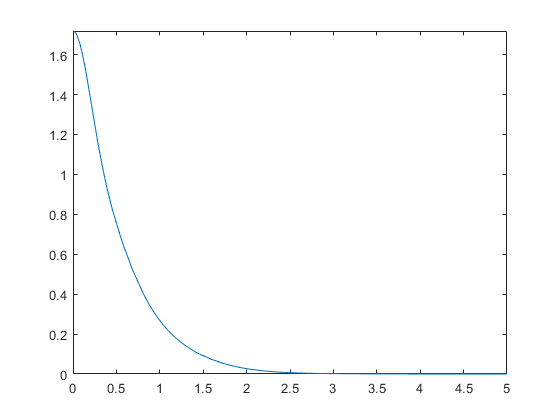

fplot(Psi,[0,5])

function F = FockMatrix(n,Z,P,D_pq,E_pq,H0)
    F = zeros(n,n);
    for p=1:n
        for q=1:n
            F_pq = 0;
            for r=1:n
                for s=1:n
                    F_pq = F_pq + P(r,s)*(D_pq{p,q}(r,s)-0.5*E_pq{p,q}(r,s));
                end
            end
            F(p,q)=F_pq + H0(p,q);
        end
    end
end